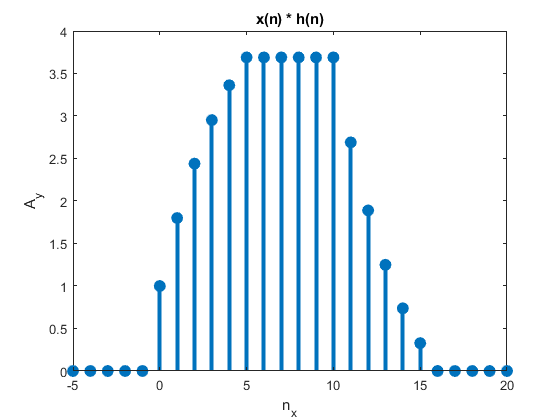

% 1)
clear 
clc
close all
n=-5:10;
u=@(n) n>=0;
x_n=(4/5).^n.*(u(n)-u(n-6));
h_n= u(n)-u(n-11); 
c=conv(x_n,h_n);
% c(c==0)=[];% Eliminamos ceros del vector 
s=-10:20;
stem(s,c,'filled','LineWidth',3),title('x(n) * h(n)'),xlabel('n_x'),ylabel('A_y'),xlim([-5,20]);

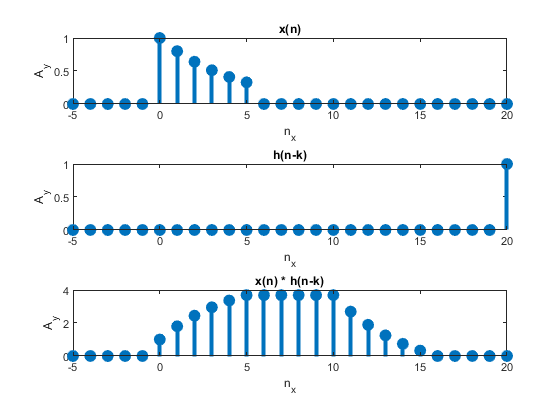

%2.Utilice MATLAB para  crear  una  animación  que  muestre el  método  gráfico para  calcularla convoluciónde  las secuenciasdel inciso  anterior. Gráfiquecada  uno  de  los  casos  analizados en el método de convolucióngráfica.
% 2)
n = -15:20;
x_nN=@(n) (4/5).^n.*(u(n)-u(n-6));
h_nN=@(n) u(n)-u(n-11);
res2=zeros(size(n));
  
for t=n
    res = conv(x_nN(t),h_nN(n-t));
    res2 =+ res2+res;
    subplot(312)
    stem(n,h_nN(n-t),'filled','LineWidth',3),title('h(n-k)'),xlabel('n_x'),ylabel('A_y'),xlim([-5,20]);
    
    subplot(313)
    
    stem(n,res2,'filled','LineWidth',3),title('x(n) * h(n-k)'),xlabel('n_x'),ylabel('A_y'),xlim([-5,20]);
    drawnow
    pause(0.1)
    subplot(311)
    stem(n,x_nN(n),'filled','LineWidth',3),title('x(n)'),xlabel('n_x'),ylabel('A_y'),xlim([-5,20]);
    
   
end